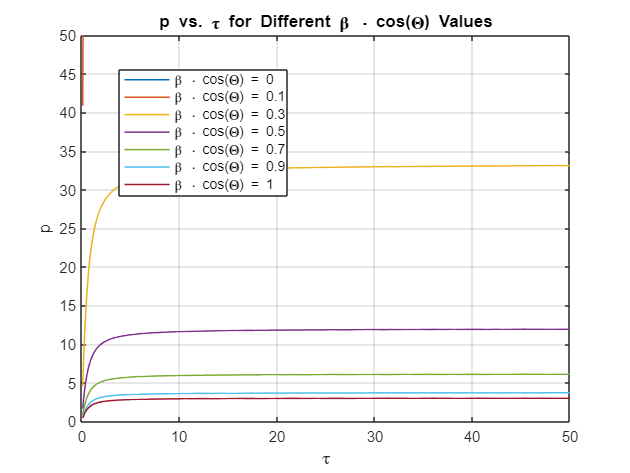

% Define the parameters
R_th = 2; % Threshold value R_th
tau_values = linspace(0, 50, 500); % Range of tau values (0 to 50)
beta_cos_theta_values = [0, 0.1, 0.3, 0.5, 0.7, 0.9, 1]; % Different values of beta * cos(theta)

% Initialize a figure
figure;

% Plot p vs. tau for different beta * cos(theta) values
for i = 1:length(beta_cos_theta_values)
    beta_cos_theta = beta_cos_theta_values(i);
    p_values = 1 ./ (abs(beta_cos_theta)^2) .* (2^R_th + (1 - exp(tau_values .* (2^R_th - 1))) ./ (tau_values .* exp(tau_values .* (2^R_th - 1))) - 1);
    
    % Plot current line with different color
    plot(tau_values, p_values, 'LineWidth', 1, 'DisplayName', ['\beta \cdot cos(\Theta) = ' num2str(beta_cos_theta)]);
    hold on;
end

xlabel('\tau');
ylabel('p');
title('p vs. \tau for Different \beta \cdot cos(\Theta) Values');
legend('Location', 'Best');
grid on;
xlim([0, 50]); % Set the x-axis limits
ylim([0, 50]); % Set the y-axis limits
hold off;